# **Plotting in MATLAB**

This lecture will cover some of the plotting options in MATLAB. We will continue to use the Framingham data set from the previous lecture. 

fram = readtable('../frmgham.xls');

For simplifying the following plotting exercises, we will just look at the first 100 patients in the data set.

fram = head(fram,100);

## Plotting data sets

There are many different ways to plot data in MATLAB and also several ways to generate these figures. Let's start by looking at the Age data from our revised Framingham data set.

age = fram.AGE;

Now that we have the Age array saved as a variable, there are two ways to plot it:

    **Option 1: **Select the variable in the Workspace, go to *Plots* tab, and select one of the plot options, such as 2-D line graph. 

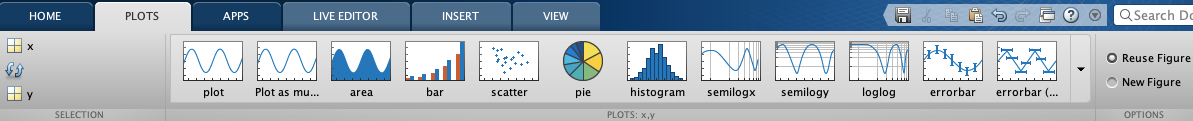

MATLAB will then create the plot for you in a new figure window and display the corresponding plotting command in the Command Window.

    **Option 2:** Use the `plot `command:

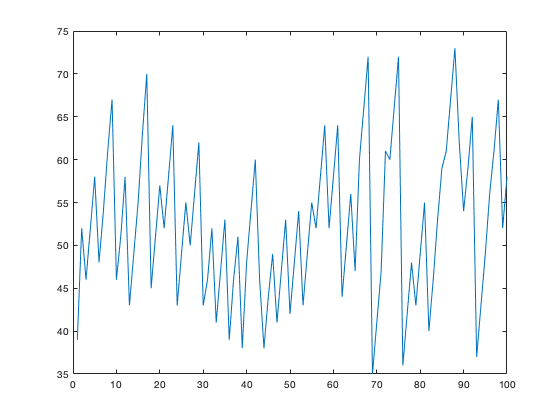

plot(age)

The figure includes the ages of all 100 patients, with age given on the y-axis and the index on the x-axis. Clearly we need to add some information to this plot and find a better way to display the data.

When viewing the plot in a figure window, we can use the* Inser*t tab to add elements such as axis labels and titles. When you are done adding these features, there is an option to generate the code for these changes (click *File *then* Generate Code)*.

As we saw, plotting with one variable outputs the index on the x-axis. However, the `plot` command is typically used with two variables. Let's plot Age vs. BMI. First store the BMI data in an array.

BMI = fram.BMI;

In addition to adding this variable, we should include axis labels and a title to our plot. Because we are using discrete data points, it also makes sense to use a different marker symbol as opposed to a line.

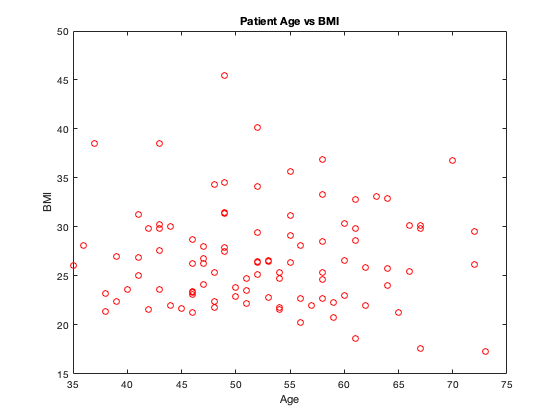

plot(age,BMI,'ro')
xlabel('Age')
ylabel('BMI')
title('Patient Age vs BMI')

### **Log-Log**

The `loglog` function simply generates a plot with a log scale on both axes. This may not necessarily be a useful tool for the variables in the Framingham data set, but let's try it on the Glucose data as an example. 

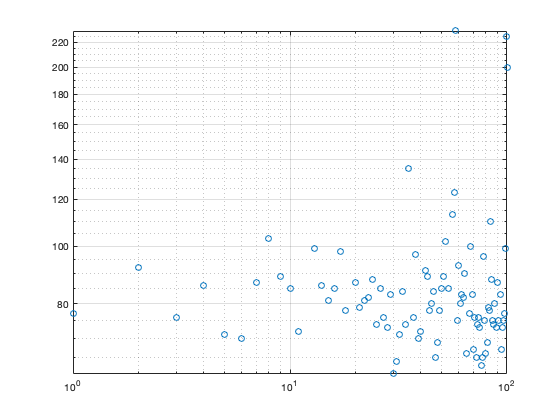

loglog(fram.GLUCOSE,'o')
grid on

### **Bar Graphs**

Bar graphs are useful for comparing data from different groups. 

Let's start with a simple example: use the `bar `command to create a graph showing the age of the first ten patients and another graph showing the BMI of the same group.

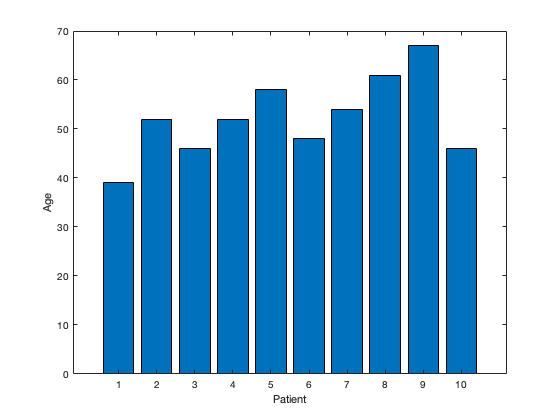

bar(age(1:10))
xlabel("Patient")
ylabel("Age")

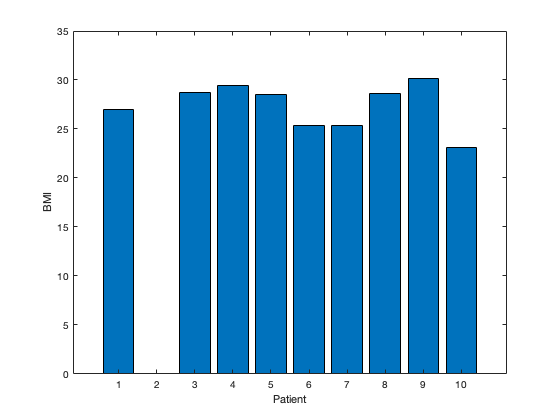

bar(BMI(1:10))
xlabel("Patient")
ylabel("BMI")

Note that the BMI for Patient 2 is missing.

For a more complicated example, create a bar graph that looks at gender versus average cigarettes smoked per day. First, we must create our bar graph categories and specify the order in which they will display:

sex = categorical({'male','female'});
sex = reordercats(sex,{'male','female'})

sex = 1×2 categorical array
     male      female 


Next, extract the cigarettes per day data for each gender and find the mean values. In the Framingham data set, males are represented by a 1 and females by a 2. Also, note that we must convert from a table to an array in order to use the *mean *function. 

male_cigs = table2array(fram(fram.SEX == 1,'CIGPDAY'));
female_cigs = table2array(fram(fram.SEX == 2,'CIGPDAY'));

mean_male_cigs = mean(male_cigs);
mean_female_cigs = mean(female_cigs);
mean_cigs = [mean_male_cigs,mean_female_cigs]

mean_cigs =    11.9388   10.5686


Finally, create the bar graph with the *bar *command. Let's make the bars blue and the bar width set to half of the available space.

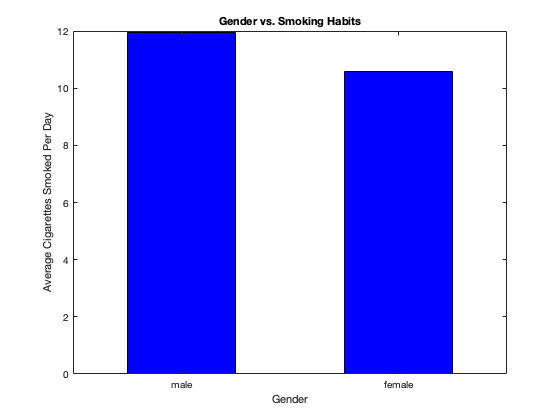

bar(sex,mean_cigs,0.5,'blue')
xlabel('Gender');
ylabel('Average Cigarettes Smoked Per Day');
title('Gender vs. Smoking Habits')

### **Pie Chart**

Pie charts are useful for looking at the composition of a group.

Let's create a pie chart which shows the gender distribution of the first 20 patients. The first step is to create an array which contains the quantity of each gender using the `sum` function.

gender_count = [sum(fram.SEX(1:20) == 1),sum(fram.SEX(1:20) == 2)]

gender_count =      4    16


The `pie` function can then be used to display the elements of this matrix as a pie chart.

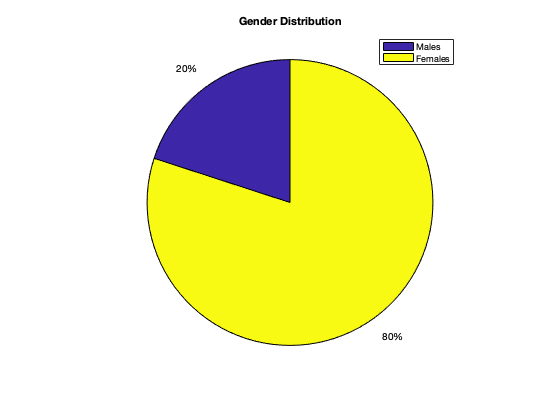

pie(gender_count)
legend({'Males','Females'})
title('Gender Distribution')

Now we will make a pie chart which shows the education levels (1 to 4) for all 100 patients. Again, the first step is extracting these four values and putting them into an array. We will use a for loop to create this array.

for i=1:4
    education_count(i)=sum(fram.educ==i);
end
education_count

education_count =     34    33    18     9


We need to make sure that the sum of our array elements is equal to 100, as we want to make sure the entire patient group is represented in the pie chart

sum(education_count)

ans = 94

We know that the Framingham data set contains some missing values. Confirm that this is the case with our education data.

nan = sum(isnan(fram.educ))

nan = 6

As expected, we are missing six data points, which would bring the total to 100. Add the missing data count to the education array so that it is incorported into the pie chart.

education_count(5) = nan;
education_count

education_count =     34    33    18     9     6


We are finally ready to make the pie chart. 

labels = {'1', '2', '3', '4','No Data'}

labels = 1×5 cell array
    {'1'}    {'2'}    {'3'}    {'4'}    {'No Data'}


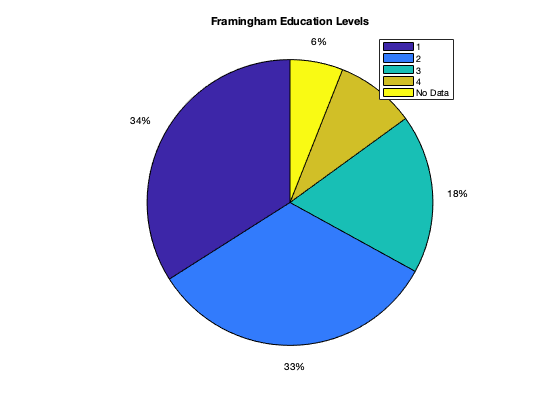

pie(education_count)
legend(labels)
title('Framingham Education Levels')

### **Histograms**

Histograms are used to look at the distribution of continuous data. The data set is displayed as a series of bins, which we can adjust to our preferences.

Use the `histogram` command to look at the distribution of age in the 100 patients (we created a 2-D line plot of this data earlier in the lesson).

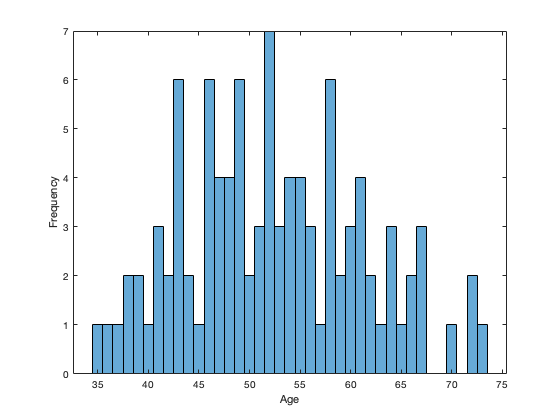

histogram(age)
xlabel("Age")
ylabel("Frequency")

The histogram plot is much more informative and easier to read than our original 2-D line plot from earlier in the lesson. We can easily see which ages are more common and determine if the distribution is fairly normal.

Next, create a histogram showing the heart rate distribution and assign it to a variable, *HR_histogram*. 

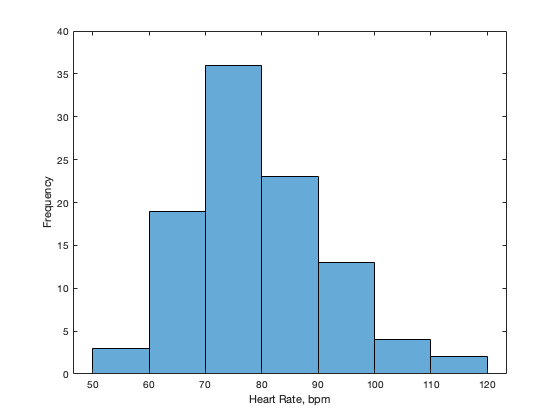

HR_histogram = histogram(fram.HEARTRTE);
xlabel('Heart Rate, bpm')
ylabel('Frequency')

By assigning the histogram to a variable, we can now use dot notation to adjust the plot properties. Break down the data into 10 bins (using `.NumBins`) and change the bin color (using `.FaceColor`). 

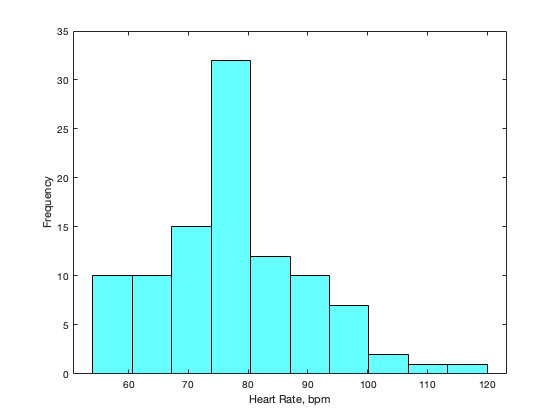

HR_histogram.NumBins = 10;
HR_histogram.FaceColor = 'cyan';

Another useful feature of the `histogram` command in MATLAB is the ability to compare two distributions in the same figure. For example, we can look at the distribution of total cholesterol in males versus females. Create an array containing the cholesterol data for males and add the code "`hold on" `afterwards.

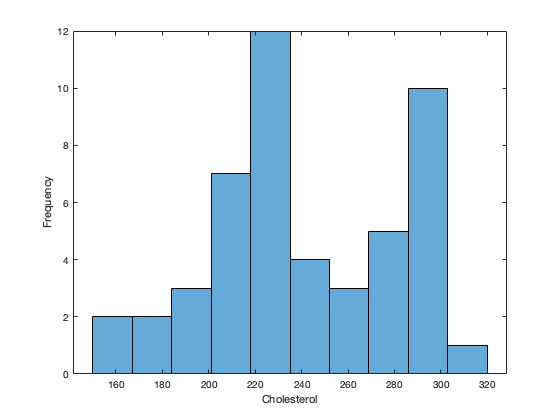

male_cholesterol = fram.TOTCHOL(fram.SEX==1);
histogram(male_cholesterol, 10)
xlabel("Cholesterol")
ylabel("Frequency")
hold on

Now create a histogram for the female cholesterol data. The histogram should be added on top of the previous plot

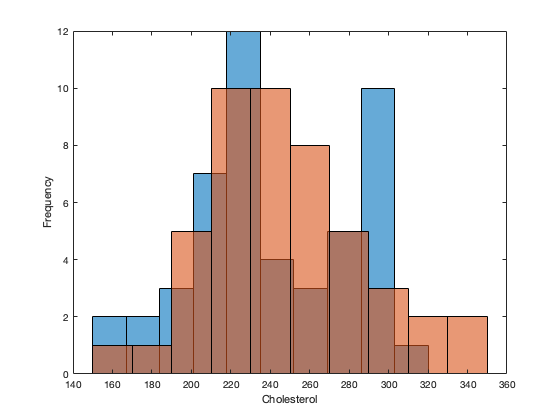

female_cholesterol = fram.TOTCHOL(fram.SEX == 2);
histogram(female_cholesterol, 10)
hold off

### Boxplots

Boxplots are also helpful for looking at data distribution. In addition to showing the shape of the distribution, boxplots display the median value, the interquartile range, minimum/maxmimum values, and outlier points.

Use the` boxplot` command to examine total cholesterol versus sex.

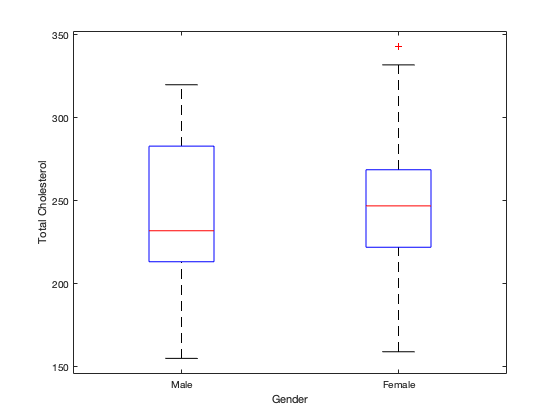

boxplot(fram.TOTCHOL,fram.SEX,'Labels',{'Male','Female'})
xlabel('Gender')
ylabel('Total Cholesterol')

As another example, create a boxplot showing how blood glucose varies between the patients without diabetes (0) and with diabetes (1).

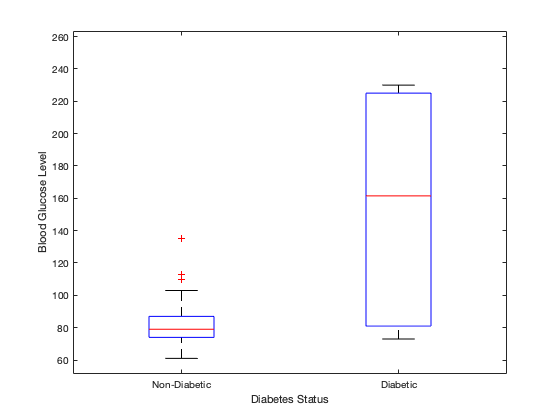

boxplot(fram.GLUCOSE,fram.DIABETES,'Labels',{'Non-Diabetic','Diabetic'})
xlabel('Diabetes Status')
ylabel('Blood Glucose Level')

### Correlation

MATLAB has many tools for examining the relationship between variables. Use the `lsline` command to plot the least squares regression line for systolic and diastolic blood pressure. 

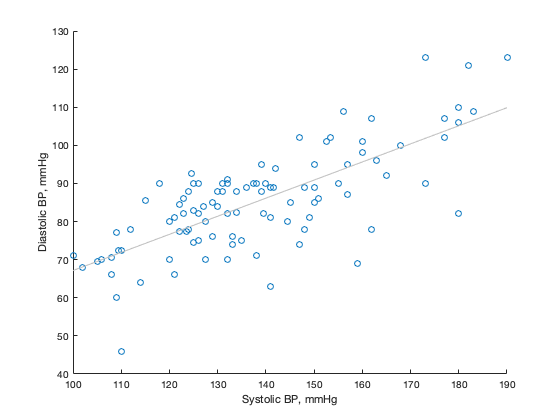

scatter(fram.SYSBP,fram.DIABP)
lsline
xlabel('Systolic BP, mmHg');
ylabel('Diastolic BP, mmHg');

Next, use the `corr` function to calculate the correlation coefficient between systolic and diastolic blood pressure. The correlation coefficient, *r, *indicates the strength and direction of the relationship between the two variables.

r = corr(fram.SYSBP,fram.DIABP)

r = 0.7429

The coefficient of determination, $r^2$, is equal to the correlation coefficient raised to the power of 2:

r ^ 2

ans = 0.5519

The coefficient of determination measures the amount of variance of one variable that can be explained by the other. In our example, $r^2$ is equal to 0.5519. This means that 55.2% of the variance in the diastolic blood pressure can be explained by the systolic blood pressure data. This can be used as an indicator for how good of a fit the least squares regression line is. 

For another example, we will determine the coefficients of correlation and determination between BMI and blood glucose levels. 

Previous work with these variables showed that there is data missing from both the BMI and Glucose data sets. We must specify for the `corr` function to only use rows that do not have missing values.

r_BMI_glucose = corr(fram.BMI,fram.GLUCOSE,"rows","complete")

r_BMI_glucose = 0.3385

r2_BMI_glucose = r_BMI_glucose .^ 2

r2_BMI_glucose = 0.1146

The correlation between these two variables is not nearly as strong as in the previous example with the systolic and diastolic blood pressures. Create a scatter plot and least-squares line to better visualize the relationship between BMI and blood glucose levels.

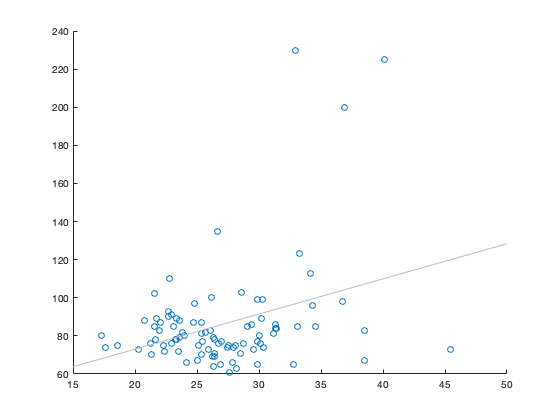

scatter(fram.BMI, fram.GLUCOSE)
lsline

## Visualizing Distributions

The `gscatter` function allows us to plot two variables against each other, such as Glucose and BMI, and then separate those data points by group. The grouping variable must be in the form of a categorical variable, such as Diabetes.

Use `gscatter` to plot glucose versus BMI, grouped by diabetes.

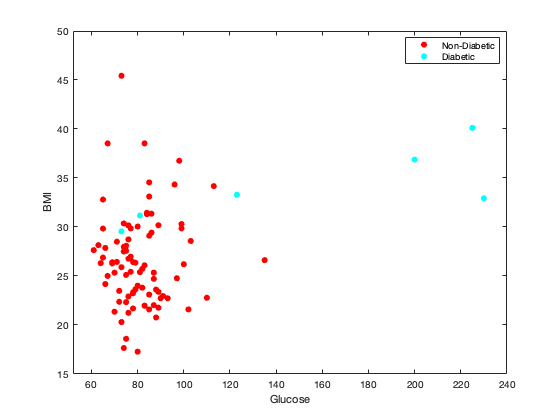

gscatter(fram.GLUCOSE, fram.BMI, fram.DIABETES)
xlabel('Glucose')
ylabel('BMI')
legend('Non-Diabetic','Diabetic')

In this example, `gscatter` makes it easy to see that essentially all of the data points at high glucose levels belong to patients with diabetes.

Repeat this process with systolic blood pressure versus total cholesterol, grouped by cardiovascular disease.

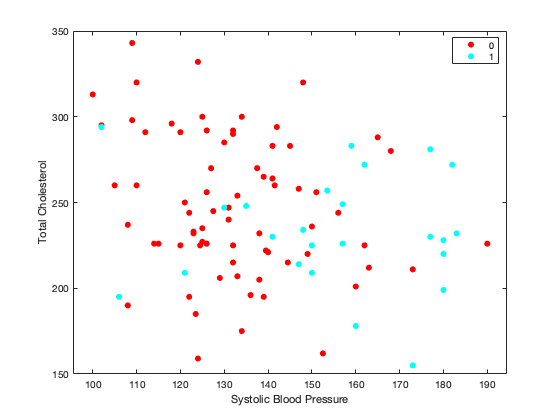

gscatter(fram.SYSBP,fram.TOTCHOL,fram.CVD)
xlabel('Systolic Blood Pressure')
ylabel('Total Cholesterol')

Unlike the last example, there aren't any apparents trends between the data groups. Upon close inspection, it appears that a slight majority of patients with higher blood pressure also suffered from CVD. In some cases, we may want to use this tool to help confirm that the data points are equally distributed throughout the different categories.

# Further Practice

### Distribution of Blood Glucose Levels

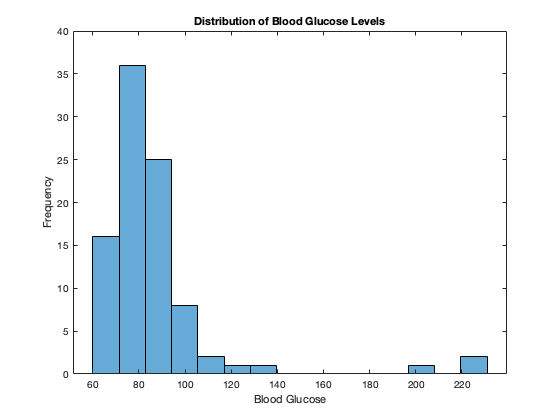

histogram(fram.GLUCOSE,15)

title('Distribution of Blood Glucose Levels')
xlabel('Blood Glucose')
ylabel('Frequency')

### Boxplot: Gender versus Heart Rate

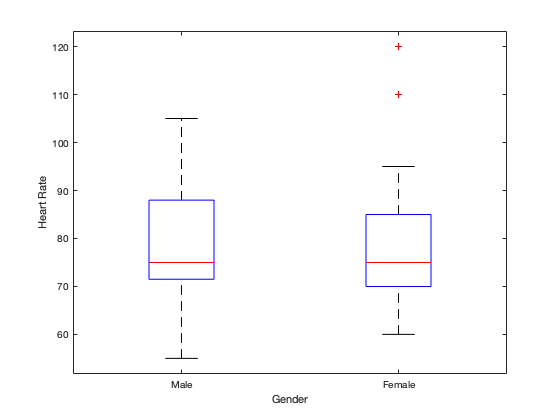

boxplot(fram.HEARTRTE, fram.SEX,'Labels',{'Male','Female'})
ylabel('Heart Rate')
xlabel('Gender')

### Education vs BMI

What is best way to show this relationship?

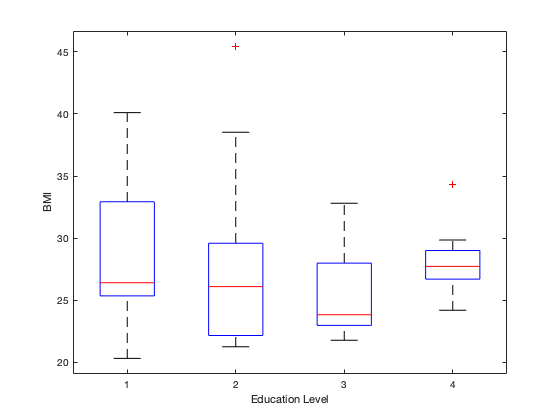

boxplot(fram.BMI,fram.educ)
ylabel('BMI')
xlabel('Education Level')